# Import data from text file

## Set up the Import Options and import the data

clear
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Location", "Area"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Geom_Horn = readtable("Geom_Horn.txt", opts)

Geom_Horn = 29×2 table
    Location       Area   
    ________    __________

          0     0.00010157
    0.16826     0.00010157
    0.17343     0.00010268
    0.17859     0.00010426
    0.18376     0.00010536
    0.18892     0.00010783
    0.19409     0.00011401
    0.19925     0.00012424
    0.20442     0.00013753
    0.20958     0.00015268
    0.21475     0.00016878
    0.21991     0.00018544
    0.22508     0.00020276
    0.23024     0.00022138
    0.23541     0.00024235
    0.24057     0.00026662


## Clear temporary variables

clear opts


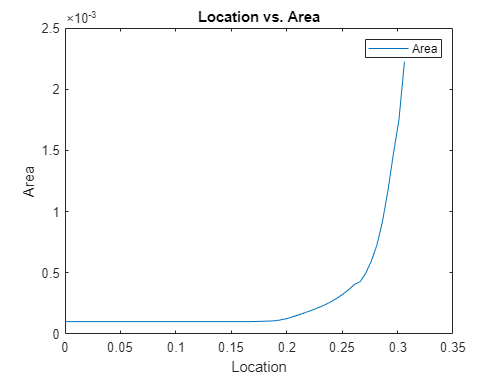

% Create plot of Geom_Horn.Location and Geom_Horn.Area
h = plot(Geom_Horn.Location,Geom_Horn.Area,'DisplayName','Area');

% Add xlabel, ylabel, title, and legend
xlabel('Location')
ylabel('Area')
title('Location vs. Area')
legend

run('Mat_Prop.m');

Geometry of horn

ac.ho.x     = Geom_Horn.Location(3:end)-Geom_Horn.Location(2:end-1);
                                                    % Length of subsection
ac.ho.s     = Geom_Horn.Area(3:end);                % Area of subsection
ac.ho.n     = size(ac.ho.x);                        % No. of subsection

ac.ho.L     = air.rho0./ac.ho.s.*ac.ho.x/2;         % L in T network of subsection
ac.ho.C     = ac.ho.s/(air.rho0*air.c^2).*ac.ho.x;  % C in T network of subsection

Geometry of parallel section

ac.ps.x     = Geom_Horn.Location(2);                % Length
ac.ps.s     = Geom_Horn.Area(2);                    % Area
ac.ps.n     = 20;                                   % No. of subsection

ac.ps.L     = air.rho0/ac.ps.s*(ac.ps.x/ac.ps.n);   % L in T network of subsection
ac.ps.C     = ac.ps.s/(air.rho0*air.c^2)*(ac.ps.x/ac.ps.n);
                                                    % C in T network of subsection

Geomtery of compressor

% ac.co.

Geomtery of mouth (plane circular piston in infinite baffle)

ac.rad.s    = Geom_Horn.Area(end);
ac.rad.a    = sqrt(ac.rad.s/pi);

ac.rad.Rm1  = 1.386*ac.rad.a^2*air.rho0*air.c;
ac.rad.Rm2  = ac.rad.s*air.rho0*air.c;
ac.rad.Cm1  = 1.89/(pi*ac.rad.a*air.rho0*air.c^2);
ac.rad.Mm1  = 8*ac.rad.a^3*air.rho0/3;